# **Procedures of Modeling LTE Uplink Transceiver**

**1. Scrambling**

**2. Modulation Mapper**

**3. Transform Precoder**

**4. RE Mapper**

**5. SC-FDMA Signal Generator**

## **Constructing the UE Structure and generating random bits**

clear;
clc;
% Create a UE-specific configuration structure, get PUSCH indices, and
% generate a bit stream sized according to configuration structure.

z_test = 0;
z_test2 = 0;

ue = lteRMCUL('A3-2');      %See Table 8.2.3.1-1 in TS 36.104
% Now, ue has: 6 RBs - Normal CP - 10 subframes - QPSK (PUSCH)
a_NULRB = 100;
a_NULRB_UE = 6;     %RBs for this specific UE
a_NCellID = 2;
a_RNTI = 10;
a_TotSubframes = 10;
a_NFrame = 0;        %Frame index
a_NSubframe = 0;

ue.NULRB = a_NULRB;
ue.NCellID = a_NCellID;
ue.RNTI = a_RNTI;
ue.TotSubframes = a_TotSubframes;
ue.NFrame = a_NFrame;
ue.NSubframe = a_NSubframe;

ue.CyclicPrefixUL = 'Normal';
ue.Shortened = 0;
chs.Modulation = 'QPSK';
chs.NLayers = 1;

[puschInd, info] = ltePUSCHIndices(ue,ue.PUSCH);
% PUSCH Indices = info.Gd = 864 = 6 RB * 12 Sub-carrier * 12 symbol
% (horizontal axis) since we are drawing only 1 subframe = 2 slots = 14
% symbols, 2 of the 14 symbols are for PUCCH and the rest are for PUSCH
% Note: info.G = # of total bits = 2 * info.Gd (QPSK symbols) = 1728

% ueDim = lteULResourceGridSize(ue);
% ueDim = 72 x 14 = (6 RBs * 12 sc) * 14 symbols

rng(5);
bits = randi([0,1],info.G,ue.PUSCH.NLayers);
% Generate random (zeros and ones) with size of (1728) x (1 layer - SISO)

## **Transmitter**

## **1.1 Interleaving**

interleavedBits = lteULSCHInterleave(ue, chs, bits, [], [], []);

## **1.2 Scrambling**

scrambledBits = lteULScramble(ue,interleavedBits);

## **2. Modulation Mapper**

modulatedSymbols = lteSymbolModulate(scrambledBits,ue.PUSCH.Modulation);

## **3. UL Transform Precoder**

precodedSymbols = lteULPrecode(modulatedSymbols,a_NULRB_UE);

## **4. RE Mapper**

% Generate resource mapping grid, populate the grid with the precoded symbols
txGrid = lteULResourceGrid(ue);
txGrid(puschInd) = precodedSymbols;

## **5. SC-FDMA Signal Generator**

% Performing SC-FDMA modulation
[txTimeDomainSig,~] = lteSCFDMAModulate(ue,txGrid);

## **Adding AWGN**

SNR = (-2:1:5);
BER = zeros(1,length(SNR));
theoBER = zeros(1,length(SNR));
for i = 1 : 1 : length(SNR)
    N0 = 0.5 / (10^(SNR(i)/10));
    N = sqrt(N0/2) / sqrt(double(2048));
    % Add noise
    noise = N*complex(randn(size(txTimeDomainSig)), randn(size(txTimeDomainSig)));
    txSignalWithNoise = txTimeDomainSig + noise;

## **Receiver**

## **5. SC-FDMA Demodulation**

    % Performing SC-FDMA Demodulation
    demodGrid = lteSCFDMADemodulate(ue,txSignalWithNoise);

## **4. RE Demapper**

    demappedGrid = demodGrid(puschInd);

## **3. UL Transform Decoder**

    decodedSymbols = lteULDeprecode(demappedGrid,a_NULRB_UE);

## **2. Modulation Demapper**

    demodSymbols = lteSymbolDemodulate(decodedSymbols,ue.PUSCH.Modulation);

## **1.2 Descrambling**

    descrambledBits = lteULDescramble(ue,demodSymbols);

## **1.1 Deinterleaving & Calculating BER**

    [out_bits,~,~,~] = lteULSCHDeinterleave(ue,chs,descrambledBits);
    % Converting bits to non-polar again
    rxBits = out_bits;
    rxBits(rxBits<0) = 0;
    rxBits(rxBits>0) = 1;
    BER(i) = sum(abs(rxBits-bits))/ double(info.G);
    theoBER(i) = berawgn(SNR(i),'psk',4,'nondiff');
end

## **Curves**

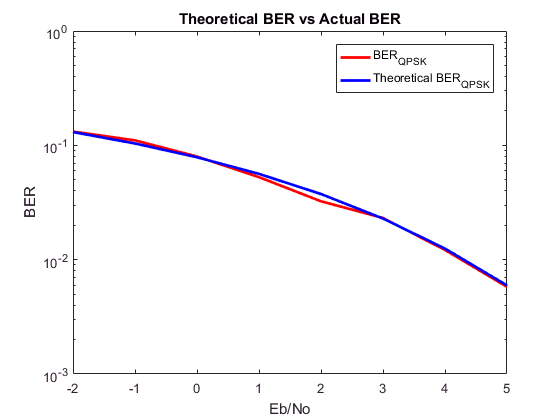

figure;
set(gca,'fontsize', 14);
h=semilogy(SNR,BER,'-red',SNR,theoBER,'-blue');
set(h,'linewidth', 2);
legend(h,'BER_Q_P_S_K','Theoretical BER_Q_P_S_K');
ylabel('BER'); 
xlabel('Eb/No');
title('Theoretical BER vs Actual BER');